%Mauro Sotelo A01707689 Raul Infante A01708002

Limipia todo

clear; clc; close all;

**Inicia codigo de la situación problema 1**

%Datos iniciales
a=2.9;
inte=0.030;
Vo=25/3.6;
Tf=02;
T=0:inte:Tf;
V=zeros(size(T));

Procede a usar el ciclo for

%Ciclo
for i = 1:length(T) 
    V(i) = Vo + a * T(i);
end
Vf=V.*3.6;

Graficar

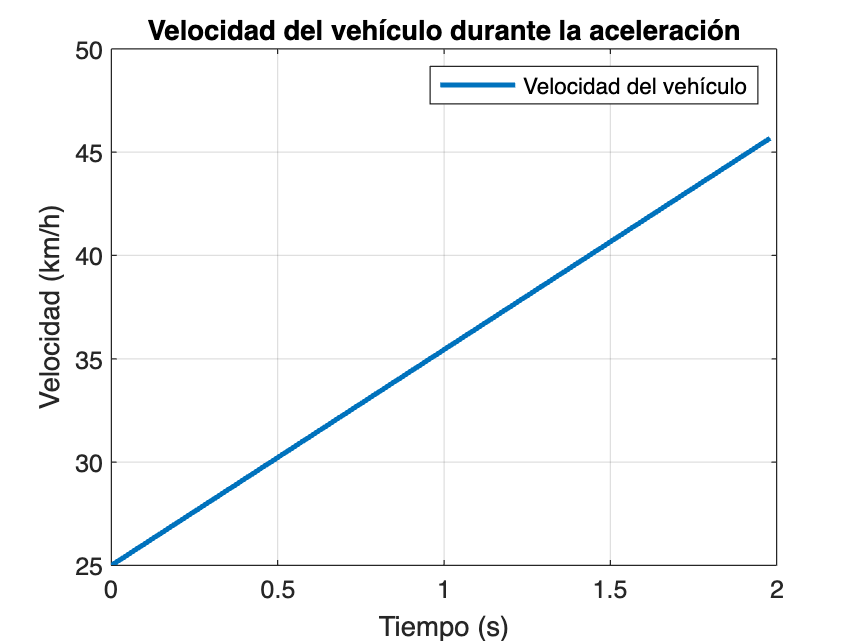

%Grafica
figure;
plot(T, Vf, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Velocidad (km/h)');
legend('Velocidad del vehículo');
title('Velocidad del vehículo durante la aceleración');
grid on


fprintf('La velocidad final del vehículo es %.2f km/h\n', Vf(end));

La velocidad final del vehículo es 45.67 km/h


**Inicia codigo de la situación problema 2**

% Datos iniciales
Vo = 150;
angulo = 30;
g = 9.81;
h = 250;

Cálculo y demas

Vox = Vo * cosd(angulo);
Voy = Vo * sind(angulo);
t_max = (2 * Voy) / g;
n = 300;
dt = t_max / n;

t = zeros(1, n);
x = zeros(1, n);
y = zeros(1, n);
Vy = zeros(1, n);


t(1) = 0;
x(1) = 0;
y(1) = 0;
Vy(1) = Voy;

Método de Euler para calcular la trayectoria

for i = 2:n
    t(i) = t(i - 1) + dt;
    x(i) = x(i - 1) + Vox * dt;
    y(i) = y(i - 1) + Vy(i - 1) * dt;
    Vy(i) = Vy(i - 1) - g * dt;
end

Graficar las componentes del vector posición

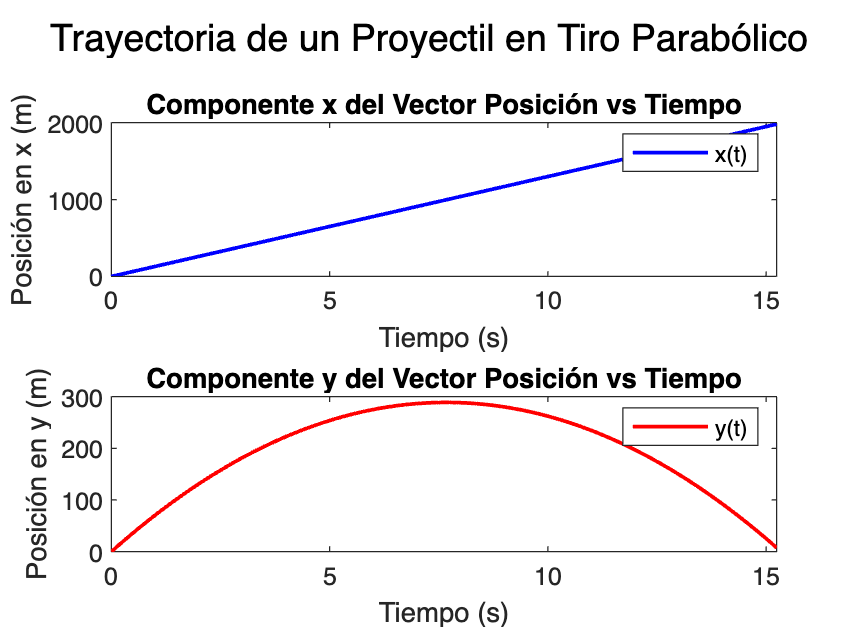

figure;
subplot(2, 1, 1);
plot(t, x, 'b', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición en x (m)');
title('Componente x del Vector Posición vs Tiempo');
legend('x(t)')

subplot(2, 1, 2);
plot(t, y, 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Posición en y (m)');
title('Componente y del Vector Posición vs Tiempo');
legend('y(t)');
sgtitle('Trayectoria de un Proyectil en Tiro Parabólico');

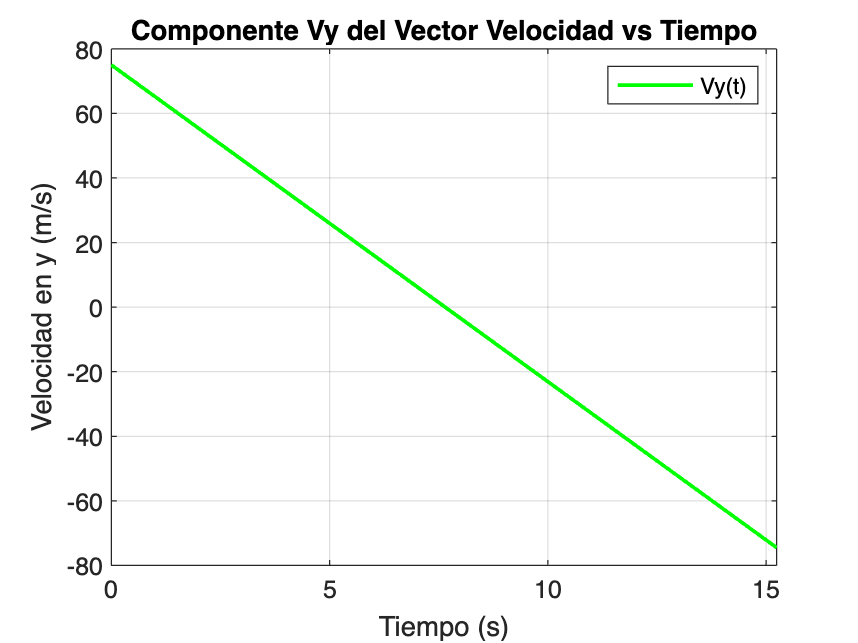


figure;
plot(t, Vy, 'g', 'LineWidth', 1.5);
xlabel('Tiempo (s)');
ylabel('Velocidad en y (m/s)');
title('Componente Vy del Vector Velocidad vs Tiempo');
legend('Vy(t)');
grid on;

**Inicia codigo de la situación problema 3**

% Datos iniciales
m = 68;
g = 9.81;
c = 22;
vi = 0;
yi = 0;
tf= 02;
n = 300;

Variables y datos

dt = tf / n;
t = 0;
Vy = vi;
y = yi;

time_values = zeros(n, 1);
Vy_values = zeros(n, 1);
y_values = zeros(n, 1);

Método de Euler

for i = 1:n
    v = sqrt(Vy^2); 
    Fr = -c * v * Vy;
    Vy = Vy - g * dt - (c / m) * v * Vy * dt;
    y = y + Vy * dt;
    
    time_values(i) = t;
    Vy_values(i) = Vy;
    y_values(i) = y;
    
    t = t + dt;
end

Graficar

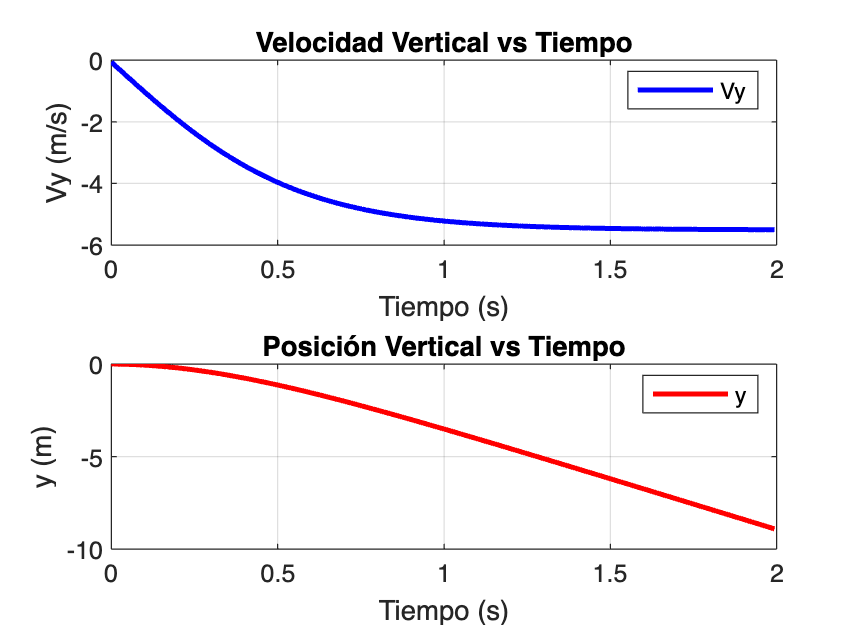

figure;
subplot(2, 1, 1);
plot(time_values, Vy_values, 'b', 'LineWidth', 2);
title('Velocidad Vertical vs Tiempo');
xlabel('Tiempo (s)');
ylabel('Vy (m/s)');
legend('Vy');
grid on;

subplot(2, 1, 2);
plot(time_values, y_values, 'r', 'LineWidth', 2);
title('Posición Vertical vs Tiempo');
xlabel('Tiempo (s)');
ylabel('y (m)');
legend('y');
grid on;